# Laboratorio 3 - Modelo diferencial de primer orden

## Parte I - Planeación de Trayectoria

En primer lugar, 

clear
clc
close all

%Parámetros del manipulador - dm
l1=6.15;
l2=1.00;
l3=7.05;
l4=sqrt(1.35^2+7.55^2);
l5=0.85;

%% DH modificado
%Creación del robot
L(1)=Link([0 l1 0 0],'modified');
L(2)=Link([0 0 l2 pi/2],'modified');
L(2).offset=pi/2;
L(3)=Link([0 0 l3 0],'modified');
L(4)=Link([0 7.55 1.35 pi/2],'modified');
L(5)=Link([0 0 0 -pi/2],'modified');
L(6)=Link([0 0 0 pi/2],'modified');

irb2400=SerialLink(L,'name','ABB IRB2400');
irb2400.tool = [eye(3) [0 0 l5]';0 0 0 1];
irb2400

 
irb2400 = 
 
ABB IRB2400 (6 axis, RRRRRR, modDH, fastRNE)                                  
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|       6.15|          0|          0|          0|             
|  2|         q2|          0|          1|      1.571|      1.571|             
|  3|         q3|          0|       7.05|          0|          0|             
|  4|         q4|       7.55|       1.35|      1.571|          0|             
|  5|         q5|          0|          0|     -1.571|          0|             
|  6|         q6|          0|          0|      1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                     

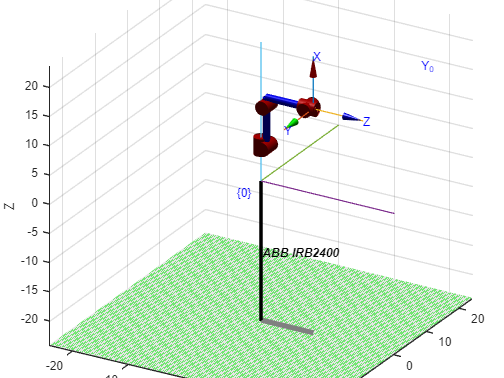

irb2400.plot([0 0 0 0 0 0])
view([30.2 24.8])
axis('auto')
hold on
trplot(eye(3),'frame','{0}','arrow','length','1')
hold off

Se seleccionó como trayectoria a seguir la ilustrada en la figura 1.

*Figura 1. Trayectoria seleccionada.*

Se definió, entonces:

ah=15.5; % alcance horizontal máximo (dm)
L=ah*0.4; 

### Creación de trayectoria

**Tramo 1**

close all

t_t1 = linspace(0,0.2,5)';
x_t1 = -7.5*ones(length(t_t1),1);
[y_t1,v_t1,a_t1] = poly3([0 0 -1.5 -5],t_t1);
z_t1 = 10*ones(length(t_t1),1);

**Tramo 2**

v_t2 = -5; %Velocidad crucero
t_t2f = 1.1/abs(v_t2);

dt = t_t1(2)-t_t1(1);
t_t2 = (dt:dt:t_t2f)';

x_t2 = -7.5*ones(length(t_t2),1);
y_t2 = y_t1(length(y_t1)) + v_t2*t_t2;
z_t2 = 10*ones(length(t_t2),1);

**Tramo 3**

w_t3 = v_t2/0.5;
t_t3f = abs((-pi+pi/2)/10);

t_t3 = (dt:dt:t_t3f)';

theta_3 = -pi/2+w_t3*t_t3;
x_t3 = -7.5*ones(length(t_t3),1);
y_t3 = y_t2(length(y_t2))+0.5*cos(theta_3);
z_t3 = 10.5+0.5*sin(theta_3);

**Tramo 4**

% v_t2 = -5; %Velocidad crucero
v_t4 = -v_t2;
t_t4f = 1.55/v_t4;

% dt = t_t1(2)-t_t1(1);
t_t4 = (dt:dt:t_t4f)';

x_t4 = -7.5*ones(length(t_t4),1);
y_t4 = -3.1*ones(length(t_t4),1);
z_t4 = z_t3(length(z_t3)) + v_t4*t_t4;

**Tramo 5**

% w_t3 = v_t2/0.5;
t_t5f = abs((-3*pi/2+pi)/10);

t_t5 = (dt:dt:t_t5f)';

theta_5 = -pi+w_t3*t_t5;
x_t5 = -7.5*ones(length(t_t5),1);
y_t5 = y_t4(length(y_t4))+0.5*(1+cos(theta_5));
z_t5 = z_t4(length(z_t4))+0.5*sin(theta_5);

**Tramo 6**

% v_t2 = -5; %Velocidad crucero
v_t6 = -v_t2;
t_t6f = 5.2/v_t6;

% dt = t_t1(2)-t_t1(1);
t_t6 = (dt:dt:t_t6f+dt)';

x_t6 = -7.5*ones(length(t_t6),1);
y_t6 = y_t5(length(y_t5)) + v_t6*t_t6;
z_t6 = z_t5(length(z_t5))*ones(length(t_t6),1);

**Tramo 7**

% w_t3 = v_t2/0.5;
t_t7f = abs((-2*pi+3*pi/2)/10);

t_t7 = (dt:dt:t_t7f)';

theta_7 = -3*pi/2+w_t3*t_t5;
x_t7 = -7.5*ones(length(t_t5),1);
y_t7 = y_t6(length(y_t6))+0.5*cos(theta_7);
z_t7 = z_t6(length(z_t6))-0.5*(1-sin(theta_7));

**Tramo 8**

% v_t2 = -5; %Velocidad crucero
v_t8 = v_t2;
t_t8f = abs(1.55/v_t8);

% dt = t_t1(2)-t_t1(1);
t_t8 = (dt:dt:t_t8f)';

x_t8 = -7.5*ones(length(t_t4),1);
y_t8 = 3.1*ones(length(t_t4),1);
z_t8 = z_t7(length(z_t7)) + v_t8*t_t8;

**Tramo 9**

% w_t3 = v_t2/0.5;
t_t9f = abs((-pi/2)/10);

t_t9 = (dt:dt:t_t9f)';

theta_9 = w_t3*t_t9;
x_t9 = -7.5*ones(length(t_t5),1);
y_t9 = y_t8(length(y_t8))-0.5*(1-cos(theta_9));
z_t9 = z_t8(length(z_t8))+0.5*sin(theta_9);

**Tramo 10**

% v_t2 = -5; %Velocidad crucero
v_t10 = v_t2;
t_t10f = abs(1.1/v_t10);

% dt = t_t1(2)-t_t1(1);
t_t10 = (dt:dt:t_t10f)';

x_t10 = -7.5*ones(length(t_t10),1);
y_t10 = y_t9(length(y_t9)) + v_t10*t_t10;
z_t10 = 10*ones(length(t_t10),1);

**Tramo 11**

t_t11 = (dt:dt:t_t1(length(t_t1)))';
x_t11 = -7.5*ones(length(t_t11),1);
[y_t11,v_t11,a_t11] = poly3([1.5 -5 0 0],t_t11);
z_t11 = 10*ones(length(t_t11),1);

### Gráfica de trayectoria

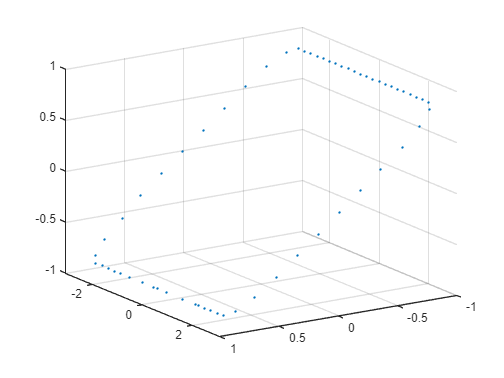

taux = [t_t1;t_t2;t_t3;t_t4;t_t5;t_t6;t_t7;t_t8;t_t9;t_t10;t_t11];

t_tray = (0:dt:dt*(length(taux)-1))';
x_tray = [x_t1;x_t2;x_t3;x_t4;x_t5;x_t6;x_t7;x_t8;x_t9;x_t10;x_t11];
y_tray = [y_t1';y_t2;y_t3;y_t4;y_t5;y_t6;y_t7;y_t8;y_t9;y_t10;y_t11'];
z_tray = [z_t1;z_t2;z_t3;z_t4;z_t5;z_t6;z_t7;z_t8;z_t9;z_t10;z_t11];

path = [x_tray y_tray z_tray];
p_cent = [-7.5 0 (max(z_tray)+min(z_tray))/2];
path_cent = path-repmat(p_cent,size(path,1),1);

R_cent = angvec2r(-pi/4,[0 1 0]);

path = zeros(size(path_cent,1),size(path_cent,2));

figure()

for i = 1:length(path_cent)
    path(i,:) = R_cent*path_cent(i,:)';%+p_cent';
end

plot3(path(:,1),path(:,2),path(:,3),'.')
view([160.91 16.41])
axis('auto')
grid on
hold off

### Cinemática inversa y obtención de perfiles para variables de articulación

% path = [x_tray y_tray z_tray];
via = zeros(length(path),6);
% [R,~] = tr2rt(irb2400.fkine([pi/2 0 -pi/4 0 0 0]))
[R,~] = tr2rt(irb2400.fkine([0 0 pi/4 0 pi/2 0]))

R =    -0.7071    0.0000   -0.7071
   -0.0000   -1.0000   -0.0000
   -0.7071    0.0000    0.7071


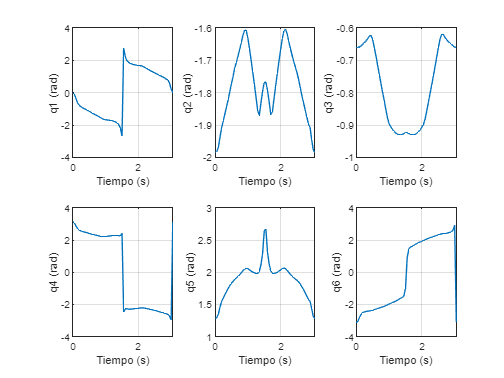

for i = 1:length(path)
    T = [R path(i,:)';0 0 0 1];
    q = ikinemIRB(irb2400,T);
    via(i,:) = q;
end

for i = 1:size(via,2)
    num = num2str(i);

    subplot(2,3,i)
    plot(t_tray,via(:,i))
    xlabel('Tiempo (s)')
    ylabel(strcat('q',num,' (rad)'))
    grid on
end

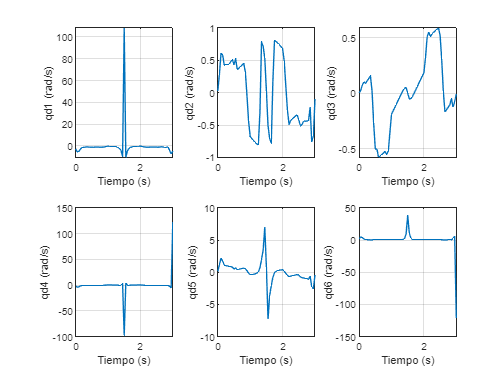

v_via = diff(via,1,1)/dt;

for i = 1:size(v_via,2)
    num = num2str(i);

    subplot(2,3,i)
    plot(t_tray(1:length(t_tray)-1),v_via(:,i))
    xlabel('Tiempo (s)')
    ylabel(strcat('qd',num,' (rad/s)'))
    grid on
end
hold off

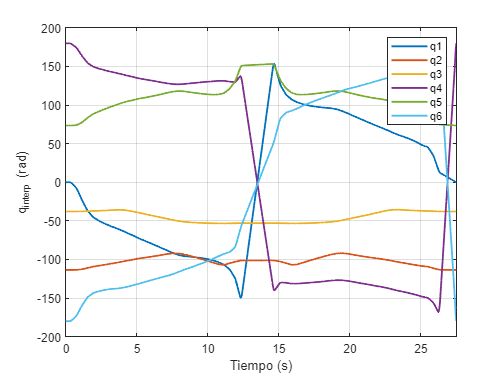

axes_vlim = deg2rad([150 150 150 360 360 450]); % rad/s

via_interp = mstraj(via,axes_vlim,[],via(1,:),dt,0.2);
via_interpd = rad2deg(via_interp);
t_tray_interp = (0:dt:dt*(length(via_interp)-1));

figure()
plot(t_tray_interp,via_interpd(:,1),t_tray_interp,via_interpd(:,2),...
     t_tray_interp,via_interpd(:,3),t_tray_interp,via_interpd(:,4),...
     t_tray_interp,via_interpd(:,5),t_tray_interp,via_interpd(:,6),'LineWidth',1.5);
legend('q1','q2','q3','q4','q5','q6')
xlim([0 t_tray_interp(length(t_tray_interp))])
xlabel('Tiempo (s)')
ylabel('q_{interp} (rad)')
grid on

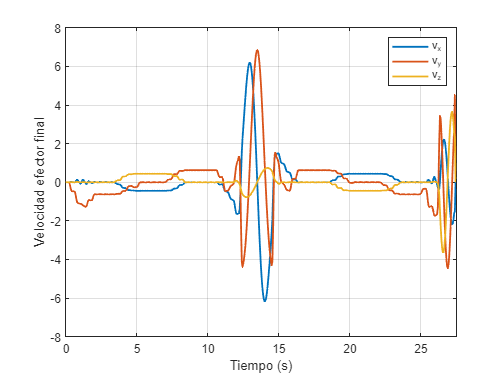

v_via_interp = diff(via_interp,1,1)/dt;
v_path = zeros(size(v_via_interp,1),size(v_via_interp,2));

for i = 1:length(v_path)-1
    J = irb2400.jacob0(via_interp(i,:),'rpy');
    v_path(i,:) = J*v_via_interp(i,:)';
end

figure()
plot(t_tray_interp(1:length(t_tray_interp)-1),v_path(:,1),...
     t_tray_interp(1:length(t_tray_interp)-1),v_path(:,2),...
     t_tray_interp(1:length(t_tray_interp)-1),v_path(:,3),...
     'LineWidth',1.5);
legend('v_x','v_y','v_z')
xlim([0 t_tray_interp(length(t_tray_interp))])
xlabel('Tiempo (s)')
ylabel('Velocidad efector final')
grid on